clear
clc

syms sweep_5 Cl_design Mdd Cl_cruise t_c sweep_25


sweep_historical = 22;
design_cl = 0.33759

design_cl = 0.3376


% t_c = 0.12;
ka = 0.87;
Mcruise = 0.75;

Mdd = Mcruise*sqrt(cosd(sweep_25))

$$Mdd = \frac{3\,\sqrt{\cos\left(\frac{\pi \,{\mathrm{sweep}}_{25}}{180}\right)}}{4}$$


% Cl_airfoil = 10*(ka - t_c - Mdd)

% Cl_cruise(sweep,t_c) = Cl_airfoil*(0.9*0.95*cosd(sweep))

Cl_airfoil(sweep_25,t_c) = (10*ka*((cosd(sweep_25))^2)) - (10*t_c*cosd(sweep_25)) - (10*Mcruise*(cosd(sweep_25)^3));
Cl_cruise = Cl_airfoil*(0.9 * 0.95)

$$Cl\_cruise(sweep\_25, t\_c) = -\frac{513\,{\cos\left(\frac{\pi \,{\mathrm{sweep}}_{25}}{180}\right)}^{3}}{80}+\frac{14877\,{\cos\left(\frac{\pi \,{\mathrm{sweep}}_{25}}{180}\right)}^{2}}{2000}-\frac{171\,t_{c}\,\cos\left(\frac{\pi \,{\mathrm{sweep}}_{25}}{180}\right)}{20}$$

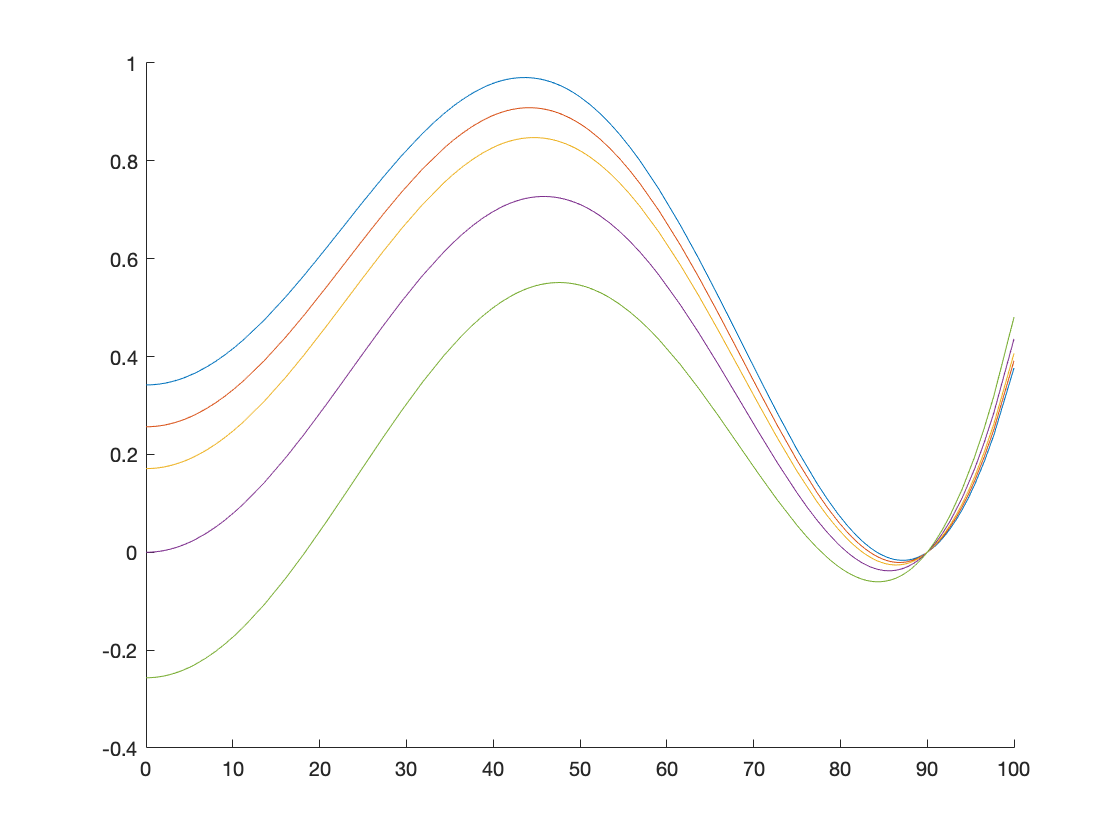



figure
hold on
fplot(@(x) Cl_cruise(x,0.08),[0,100])
fplot(@(x) Cl_cruise(x,0.09),[0,100])
fplot(@(x) Cl_cruise(x,0.10),[0,100])
fplot(@(x) Cl_cruise(x,0.12),[0,100])
fplot(@(x) Cl_cruise(x,0.15),[0,100])


% fcn = subs(Cl_cruise,t_c,0.12);
options = optimset('Display','off')

options = struct with fields:
                   Display: 'off'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
      

required_sweep_08 = fsolve(@(x) double(Cl_cruise(x,0.08)) - design_cl, 20,options)

required_sweep_08 = -0.0237

required_sweep_09 = fsolve(@(x) double(Cl_cruise(x,0.09)) - design_cl, 20,options)

required_sweep_09 = 10.3979

required_sweep_10 = fsolve(@(x) double(Cl_cruise(x,0.10)) - design_cl, 20,options)

required_sweep_10 = 15.1157

required_sweep_12 = fsolve(@(x) double(Cl_cruise(x,0.12)) - design_cl, 20,options)

required_sweep_12 = 22.2210

required_sweep_15 = fsolve(@(x) double(Cl_cruise(x,0.15)) - design_cl, 20,options)

required_sweep_15 = 31.4251


Mdd_08 = double(subs(Mdd,sweep_25,required_sweep_08))

Mdd_08 = 0.7500

Mdd_09 = double(subs(Mdd,sweep_25,required_sweep_09))

Mdd_09 = 0.7438

Mdd_10 = double(subs(Mdd,sweep_25,required_sweep_10))

Mdd_10 = 0.7369

Mdd_12 = double(subs(Mdd,sweep_25,required_sweep_12))

Mdd_12 = 0.7216

Mdd_15 = double(subs(Mdd,sweep_25,required_sweep_15))

Mdd_15 = 0.6928


Cl_section_design_08 = design_cl/(0.9*0.95*cosd(required_sweep_08))

Cl_section_design_08 = 0.3948

Cl_section_design_09 = design_cl/(0.9*0.95*cosd(required_sweep_09))

Cl_section_design_09 = 0.4014

Cl_section_design_10 = design_cl/(0.9*0.95*cosd(required_sweep_10))

Cl_section_design_10 = 0.4090

Cl_section_design_12 = design_cl/(0.9*0.95*cosd(required_sweep_12))

Cl_section_design_12 = 0.4265

Cl_section_design_15 = design_cl/(0.9*0.95*cosd(required_sweep_15))

Cl_section_design_15 = 0.4627